clear
clc

music = audioread('fmt.wav'); %读文件
cla reset
plot(music);
mabs = abs(music); %时域幅度谱

由于平方会增大信号间的峰值差异，一些较小的信号可能被淹没，于是改用取绝对值

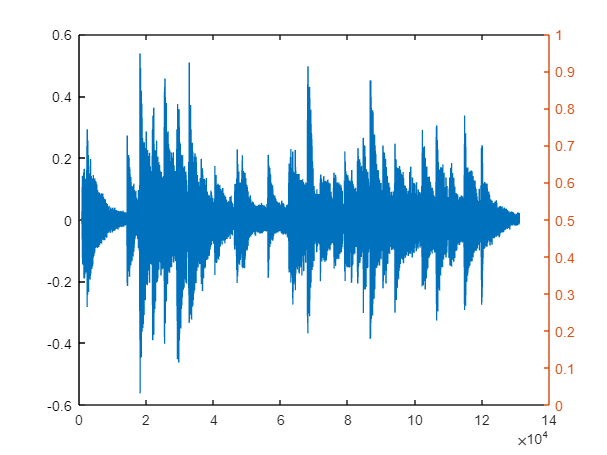

yyaxis left
plot(mabs);

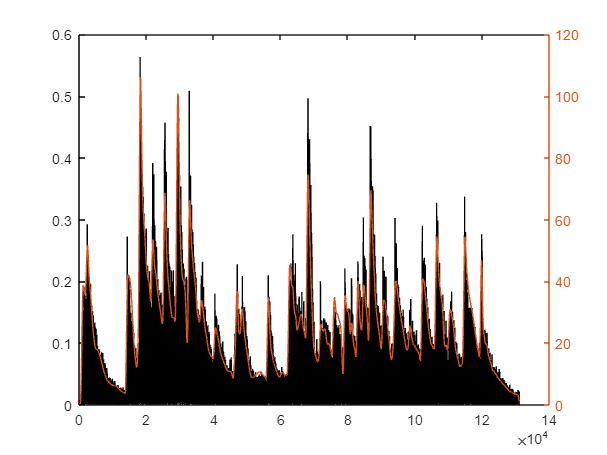

hold on
windowsize = 1067; %平滑窗大小
offsetmax = windowsize-1;
negoffsetmax = -offsetmax;
offset = 114;%偏置大小
smusic = smoothwindow(mabs,windowsize,offset);
yyaxis right
plot(smusic);
hold off

参考了https://blog.csdn.net/matrix_laboratory/article/details/53709638第2节图示的流程，了解了若干窗函数，除此之外并未借鉴任何除官方文档以外的资料和代码

经过用Numeric Slider的实验，在8000采样率下，发现Hann窗的windowsize为1067，对应offset为114时对此吉他的包络提取效果较好

加偏置的原因：我发现此吉他的响应上升和衰减均较快，包络呈现**_|\__**形态，不对称，故不能保证平滑后峰值与原谱峰值对应，故对Hann窗加一个偏移

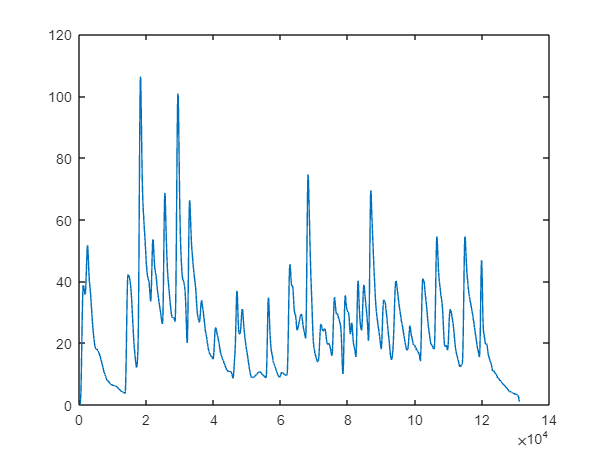

cla reset
plot(smusic);

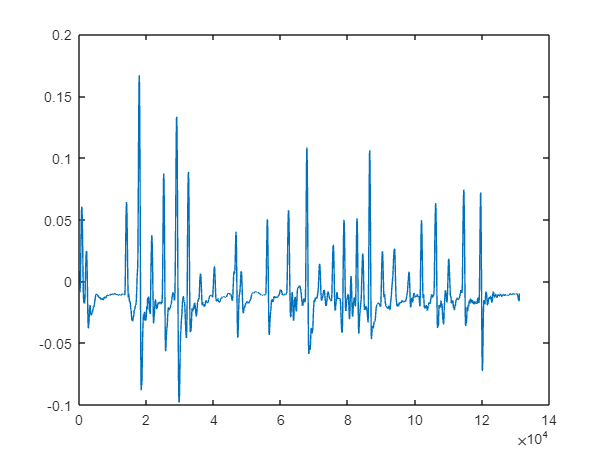

difn =1;
threshold = 0.01;%阈值
dmusic = differential(smusic,difn)-threshold;
plot(dmusic);

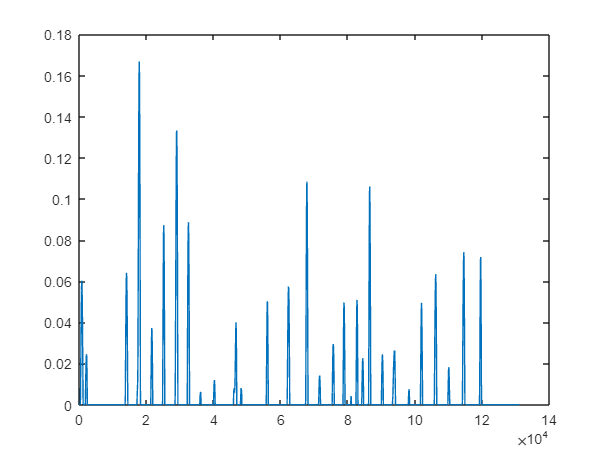

dmusic(dmusic<0)=0;
plot(dmusic);

增设阈值后，得到较为理想的峰值图像，接下来搜索非0值，整理结果

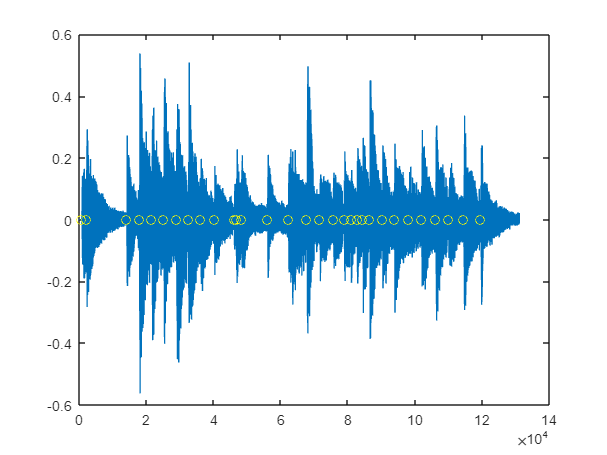

vec = findbeatstarts(dmusic);
t = 1:length(music);
plot(t,music);
hold on
scatter(vec,zeros(1,length(vec)),'yellow');
hold off

可以看出，识别结果较为准确